# **TDSÑ: Práctica 3**

## **AVISO**

**Para poder ejecutar el código de esta práctica necesita tener instaladas la siguiente caja de herramientas de MATLAB:**

- ***Signal Processing Toolbox***

El siguiente código comprueba si está instalada.

check_toolboxes("SG", 'es')

Correcto.


Antes de comenzar ejecute el siguiente código para borrar las variables del espacio de trabajo, añadir la caja de herramientas del laboratorio, establecer un tamaño de gráfica por defecto y eliminar algunos avisos del editor.

clear, subplot
disp(matlab.addons.install("TDSÑ_LABS/Laboratorio TDSÑ.mltbx"))

           Name           Version    Enabled                  Identifier              
    __________________    _______    _______    ______________________________________

    "Laboratorio TDSÑ"     "1.6"      true      "f0cd2efa-daf1-4684-90dc-b476e9c0e6d9"



set(groot, 'DefaultFigurePosition', [0, 0, 500, 300])
%#ok<*NASGU>
%#ok<*ASGLU>

## **Instrucciones**

- *Escriba las direcciones de los correo-e suya y de su pareja en las variables *`alumno_1`* y *`alumno_2`* y ejecute la sección.*

- *La práctica incluye varias tareas que debe contestar en este mismo archivo en las zonas marcadas desde *`% SU CÓDIGO AQUÍ`* hasta *`% --------------.`

- *No cambie las llamadas a la función *`check_task`.

- *Cuando termine las tareas guarde este archivo y súbalo a la carpeta de entrega de Moodle. No cambie el nombre ni el tipo de archivo.*

alumno_1 = 'ignacio.aguirrec@alumnos.upm.es'; 
alumno_2 = 'ines.valdivielso@alumnos.upm.es';
check_task(300, 'es');

>>>>> [3:0:0] Correcto.


## Introducción

En esta práctica se presentan las herramientas que proporciona MATLAB para trabajar con sistemas LTI racionales causales, o lo que es lo mismo, con filtros digitales. El desarrollo de la sesión se basa en algunos filtros concretos aunque las herramientas que se estudian son válidas para cualquier filtro discreto.

## 1. Sistemas LTI racionales

La función de transferencia de un sistema LTI racional responde a la expresión


$$\displaystyle H(z)=\frac{{\sum_{k=0}^{M}}b_{k}z^{-k}}{{\sum_{k=0}^{N}}a_{k}z^{-k}}$$


a la que habría que añadir la correspondiente región de convergencia. $H(z)$ es una función racional cociente de dos polinomios en la variable $z$ tradicionalmente designados como $B(z)$ el numerador y $A(z)$ el denominador; es decir$H(z) = \frac{B(z)}{A(z)}$. Los sistemas causales de este tipo reciben el nombre genérico de filtros digitales.

MATLAB incorpora un amplio repertorio de funciones para el análisis, diseño, representación e implementación de los filtros digitales. Todas las funciones siguen la nomenclatura del libro de texto de la asignatura y usan los coeficientes de los polinomios $B(z)$ y $A(z)$ de la función racional $H(z)$ expresados en potencias de $z^{-1}$.

### 1.1. Coeficientes

En MATLAB un polinomio se representa mediante un vector fila con los coeficientes ordenados en potencias **decrecientes**. Por ejemplo, el polinomio $X(z)=-2z^{-1}+3z^{-3}$ se representa con el vector

X = [0, -2, 0, 3];

Nótese que los coeficientes del término independiente y en $z^{-2}$ son nulos y que la longitud del vector es el grado del polinomio +1. Un polinomio de grado $N$ se representa siempre con un vector de longitud $N+1$.

Es importante que los coeficientes nulos se especifiquen correctamente porque cada coeficiente ocupa un lugar concreto en el vector; el coficiente $b_k$ del vector `B` ocupa la posición `B(k+1)`; por ejemplo el coeficiente $b_1$ es `B(2)`.

En ocasiones el polinomio puede reducirse a un escalar porque solo existe el término independiente. Por ejemplo, el denominador de un sistema no recursivo es $A(z)=1$. En este caso basta con escribir

A = 1;

porque todas las variables MATLAB son matrices, en este caso de tamaño 1x1, lo que equivale a un vector con un único componente. No es necesario, por tanto, escribir:

A = [1];

El editor de MATLAB avisa con una advertencia (*warning*) si detecta expresiones innecesarias de este tipo. Puede comprobarlo colocando el ratón bajo la llave de apertura en el código anterior.

En MATLAB la representación de un filtro digital se hace usando los dos vectores correspondientes a los polinomios numerador $B(z)$ y denominador $A(z)$ de la función de transferencia racional, en este orden. Y, recuerde, siempre en potencias decrecientes, por lo que el primer elemento del vector es el término independiente del polinomio, el segundo elemento es el coeficiente en $z^{-1}$, el tercero el coeficiente en $z^{-2}$ y así sucesivamente, sin olvidar los coeficientes nulos.

**Importante:** en MATLAB la región de convergencia **NO **se especifica de ninguna forma y se asume causalidad por defecto.

#### Tarea 3.1.1

Se desean usar las siguientes funciones de transferencia en MATLAB:

- 
$$H_1(z)=\frac{1}{\frac{1}{5}-\frac{1}{3}z^{-2}+z^{-3}},\ |z| > 2.03$$


- 
$$H_2(z)=-\frac{1}{4}+z^{-2},\ |z| > 0 $$


Defina los correspondientes vectores de coeficientes `B1`, `A1`, `B2` y `A2`.

% SU CÓDIGO AQUÍ
B1 = 1;
A1 = [1/5, 0, -1/3, 1];

B2 = [-1/4, 0 , 1];
A2 = 1;

% --------------
check_task(311, 'es')

>>>>> [3:1:1] Correcto.


#### Tarea 3.1.2

Se desean usar las siguientes ecuaciones en diferencias en MATLAB:

- $y[n]-\frac{1}{3}y[n-1]+\frac{1}{5}y[n-3]=x[n]-\frac{1}{4}x[n-2]$ (sistema 3)

- $y[n]=x[n]-\frac{1}{4}x[n-1]+\frac{1}{3}x[n-3]-x[n-4]$ (sistema 4)

Defina los correspondientes vectores de coeficientes `B3`, `A3`, `B4` y `A4`.

% SU CÓDIGO AQUÍ
B3 = [1, 0 , -1/4];
A3 = [1, -1/3, 0, 1/5];

B4 = [1, -1/4, 0, 1/3, -1];
A4 = 1;

% --------------
check_task(312, 'es')

>>>>> [3:1:2] Correcto.


### 1.2.- Filtrado

La función MATLAB para filtrar señales es [`filter`](matlab: doc filter). Su sintaxis más habitual es `y = filter(B, A, x)` donde `B` y `A` son los coeficientes del filtro, `x` la señal de entrada e `y` la señal de salida, cuya longitud es siempre la misma que la de la señal de entrada.

En el siguiente ejemplo se filtra la señal contenida en del archivo `speech.wav` y se muestra el intervalo $1100 \le n \le 1300$ de la entrada y la salida.

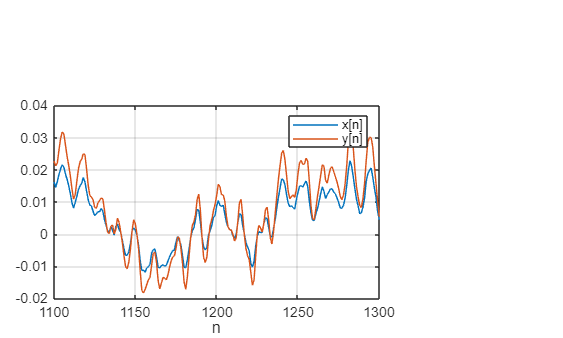

[x, ~] = audioread("speech.wav");
B = [1, 1/2, -1/4]; A = [1, -1/3, 1/5];
y = filter(B, A, x);
N = (1100:1300)';
plot_sig(N, [x(N), y(N)], "", "n")
legend("x[n]", "y[n]")

Como el número de muestras es "grande" la representación se hace como si se tratara de una señal continua (con [`plot`](matlab: doc plot) en vez de [`stem`](matlab: doc stem)). Esta consideración es válida para todas las gráficas posteriores.

Note que los dos primeros parámetros de la función [`filter`](matlab: doc filter) son `B` (numerador) y `A` (denominador). Todas las funciones de análisis de MATLAB siguen este mismo patrón.

#### Tarea 3.1.3

Genere la señal $x[n]=\sin\left(\frac{\pi}{10}n\right)$ en el intetvalo $0\le n\le 49$ y fíltrela con el sistema $H(z)$ cuya función de transferencia es $H(z)=\frac{0.0036+0.0072z^{-1}+0.0036z^{-2}}{1-1.82z^{-1}+0.84z^{-2}}$. Asigne la salida al vector `y`.

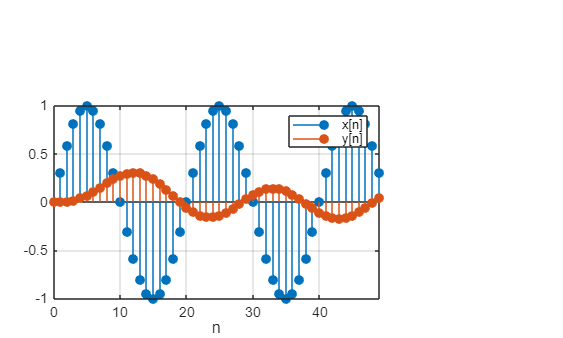

clear x y
% SU CÓDIGO AQUÍ
N = (0:49)';
x = sin((pi*N)/10);
B = [0.0036, 0.0072, 0.0036]; 
A = [1, -1.82, 0.84];
y = filter(B, A, x); 
% --------------
plot_sig(N, [x, y], "", "n")
legend("x[n]", "y[n]")

check_task(313, 'es')

>>>>> [3:1:3] Correcto.


## 2. Análisis

En los siguientes apartados se trabaja con dos filtros:

- IIR: $H_{IIR}(z)=\frac{0.5+0.75z^{-1}+0.5z^{-2}}{1-0.2z^{-1}+0.5z^{-2}}$

- FIR: $H_{FIR}(z)= 1+0.89z^{-1}-0.93z^{-2}-1.95z^{-3}-0.23z^{-4}+0.75z^{-5}-0.48z^{-6}$

Los vectores de coeficientes son:

B_iir = [.5, .75, .5];
A_iir = [1, -.2, .5];
B_fir = [1, .89, -.93, -1.95, -.23, .75, -.48];
A_fir = 1;

Como verá, estos sistemas no son buenos como filtros selectivos en frecuencia. Su propósito es meramente ilustrativo.

### 2.1 Respuesta al impulso

La respuesta al impulso se obtiene con la función [`impz`](matlab: doc impz) indicando los vectores de coeficientes. La función devuelve la señal y, opcionalmente el vector de índices. En el caso FIR la función calcula todos los valores de la respuesta, mientras que en el caso IIR la función trunca la secuencia cuando los valores son casi nulos. Alternativamente, puede pasarse como tercer parámetro la longitud de la respuesta requerida.

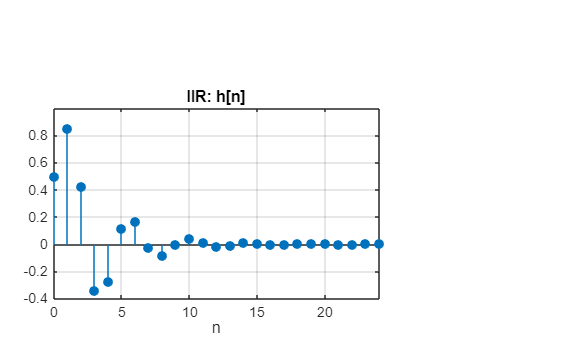

[h_iir, n_iir] = impz(B_iir, A_iir, 25);
plot_sig(n_iir, h_iir, "IIR: h[n]", "n")

#### Tarea 3.2.1

Calcule con la función [`impz`](matlab: doc impz) 10 puntos de la respuesta al impulso y el vector de índices del filtro FIR. Asígne el resultado a las variables `h_fir` y `n_fir`, respectivamente.

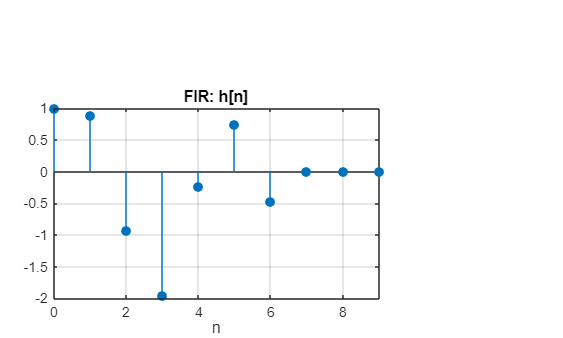

clear n_fir h_fir
% SU CÓDIGO AQUÍ
B_fir = [1, .89, -.93, -1.95, -.23, .75, -.48];
A_fir = 1;
[h_fir, n_fir] = impz(B_fir,  A_fir, 10);
% --------------
plot_sig(n_fir, h_fir, "FIR: h[n]", "n")

check_task(321, 'es')

>>>>> [3:2:1] Correcto.


Existen otras formas de calcular la respuesta al impulso: filtrando una $\delta[n]$ o, en el caso de un sistema IIR, a partir de la descomposición en fracciones simples de la función de transferencia usando la función [`residuez`](matlab: doc residuez).

#### Tarea 3.2.2

Genere una señal $\delta[n]$ en el intervalo $0 \le n \le 9$ y asígnela a la variable `delta`. Use la función [`filter`](matlab: doc filter) para calcular la respuesta al impulso $h[n]$ del filtro FIR. Asigne esta respuesta a la variable `h_fir`.

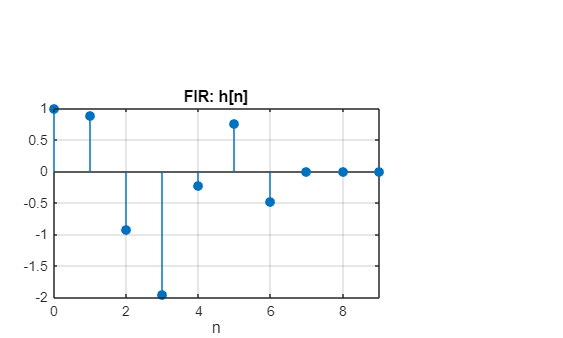

clear delta h_fir
% SU CÓDIGO AQUÍ
N = (0:9)';
delta = double (N==0);
B_fir = [1, .89, -.93, -1.95, -.23, .75, -.48];
A_fir = 1;
h_fir = filter(B_fir, A_fir, delta);
% --------------
plot_sig(N, h_fir, "FIR: h[n]", "n")

check_task(322, 'es')

>>>>> [3:2:2] Correcto.


### 2.2 Respuesta en frecuencia

La función MATLAB que calcula la respuesta en frecuencia de un filtro discreto es [`freqz`](matlab: doc freqz). Esta función puede usarse de múltiples formas; la más simple es `[H, w] = freqz(B, A)`, que calcula y devuelve el valor de la respuesta en frecuencia `H` del filtro con coeficientes `B` y `A` en $N=512$ frecuencias `w` equiespaciadas en el intervalo $[0, \pi)$.

[H_iir, w] = freqz(B_iir, A_iir);

Si se desea un número de frecuencias distinto puede indicarse como tercer parámetro de la función y si se quiere el intervalo $[0,2\pi)$ se puede añadir el parámetro `'whole'`. Por ejemplo, $N=1024$ muestras en el intervalo $[0,2\pi)$ se calculan con

[H_iir, w] = freqz(B_iir, A_iir, 1024, 'whole');

La respuesta en frecuencia es, en general, una función compleja de variable real por lo que es preciso analizar por separado su módulo y su fase.

The frequency response is, in general, a complex function of a real variable, so it is necessary to analyze its magnitude and phase separately.

#### Módulo

El módulo de la respuesta en frecuencia se calcula con la función [`abs`](matlab: doc abs). Con el siguiente código se representa el módulo en unidades lineales en el intervalo $[0, \pi)$

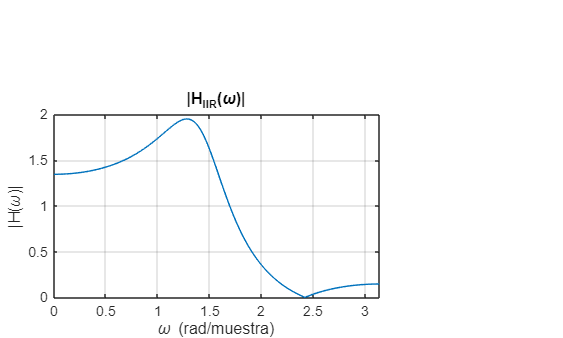

[H_iir, w] = freqz(B_iir, A_iir);
plot_spec(w, abs(H_iir), "|H_{IIR}(\omega)|", "\omega (rad/muestra)") 
ylabel("|H(\omega)|")

La función [`plot_spec`](matlab: help plot_spec) de la caja de herramientas facilita la representación de espectros.

Con el siguiente código se representa el módulo en decibelios

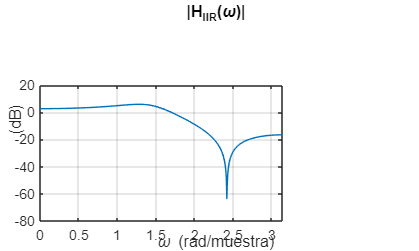

plot_spec(w, mag2db(abs(H_iir)), "|H_{IIR}(\omega)|", "\omega (rad/muestra)") 
ylabel("(dB)")

#### Tarea 3.2.3

Calcule el módulo en decibelios de la respuesta en frecuencia del filtro FIR en $N=1024$ frecuencias en el intervalo $[0,\pi)$. Asigne el resultado a las variable `mH_fir` y `w`.

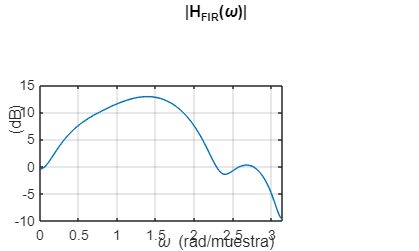

clear w mH_fir
% SU CÓDIGO AQUÍ
B_fir = [1, .89, -.93, -1.95, -.23, .75, -.48];
A_fir = 1;
[H_fir, w] = freqz(B_fir, A_fir, 1024);
mH_fir = mag2db(abs(H_fir));
% --------------
plot_spec(w, mH_fir, "|H_{FIR}(\omega)|", "\omega (rad/muestra)") 
ylabel("(dB)")

check_task(323, 'es')

>>>>> [3:2:3] Correcto.


#### Fase y retardo de grupo

#### Phase and group delay

La otra parte de la respuesta en frecuencia es la fase. En MATLAB el ángulo de un número complejo (es decir, su fase) se calcula con la función [`angle`](matlab: doc angle), así que la fase del filtro IIR es:

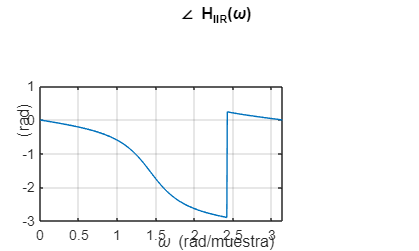

[H_iir, w] = freqz(B_iir, A_iir);
pH = angle(H_iir);
plot_spec(w, pH, "\angle H_{IIR}(\omega)", "\omega (rad/muestra)") 
ylabel("(rad)")

En la figura se observa que entre los valores de frecuencia $2.4176$ y $2.4237$ hay una discontinuidad de amplitud $\pi$. Estos saltos son ficticios y se deben a los cambios de signo de la respuesta compleja $H(\omega)$.

Los saltos de amplitud $2\pi$ que pudieran aparecer también son ficticios ya que $H(\omega)$ es una función continua. Se producen porque la función [`angle`](matlab: doc angle) usa internamente la función [`atan2`](matlab: doc atan) que calcula el valor principal en el intervalo $[-\pi, \pi)$. Así pues, la función [`angle`](matlab: doc angle) calcula $\mathrm{ARG} [H(\omega)]$.

Para quitar los posibles saltos de amplitud $2\pi$ el valor principal debe "desenrollarse" con la función [`unwrap`](matlab: doc unwrap):

plot_spec(w, unwrap(pH), "\angle H_{IIR}(\omega)", "\omega (rad/muestra)") 
ylabel("(rad)")

Note que la fase desenrollada aún presenta los saltos de amplitud $\pi$.

#### Tarea 3.2.4

Calcule la fase (sin desenrrollar) de la respuesta en frecuencia del filtro FIR en $N=1024$ frecuencias en el intervalo $[0,\pi)$. Asigne el resultado a las variables `pH_fir` y `w`. Calcule también la fase desenrrollada y asígnela a la variable `upH_fir`.

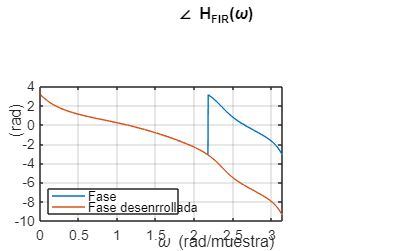

clear w pH_fir upH_fir
% SU CÓDIGO AQUÍ
B_fir = [1, .89, -.93, -1.95, -.23, .75, -.48];
A_fir = 1;
[H_fir, w] = freqz(B_fir, A_fir, 1024);
pH_fir = angle(H_fir);
upH_fir = unwrap(pH_fir);
% --------------
plot_spec(w, [pH_fir, upH_fir], "\angle H_{FIR}(\omega)", "\omega (rad/muestra)") 
legend("Fase", "Fase desenrrollada", Location="southwest"); 
ylabel("(rad)")

check_task(324, 'es')

>>>>> [3:2:4] Correcto.


Para visualizar más claramente el comportamiento de la función de fase continua $\phi(\omega)=\mathrm{arg}[H(\omega)]$ es costumbre representar el retardo de grupo:


$$\displaystyle \tau_g (\omega)=-\frac{\mathrm{d}\phi(\omega)}{\mathrm{d}\omega}$$


cuyo cálculo en MATLAB se hace con la función [`grpdelay`](matlab: doc grpdelay):

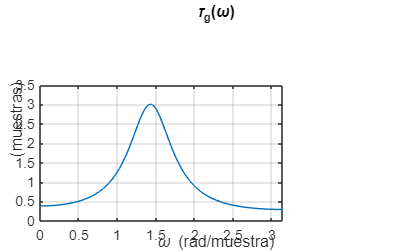

[tau_iir, w] = grpdelay(B_iir, A_iir);
plot_spec(w, tau_iir, "\tau_g(\omega)", "\omega (rad/muestra)"); 
ylabel("(muestras)"); 

Esta función admite también como parámetros el número de frecuencias y `'whole'` para indicar el intervalo $[0,2\pi)$.

Si se conoce el retardo de grupo $\tau_g(\omega)$ se puede obtener la fase continua teniendo en cuenta que


$$\displaystyle \phi(\omega)=-\int_{-\infty}^{\omega} \tau_g(\omega) \mathrm{d}\omega$$


que en MATLAB puede calcularse numéricamente con la función [`cumtrapz`](matlab: doc cumtrapz).

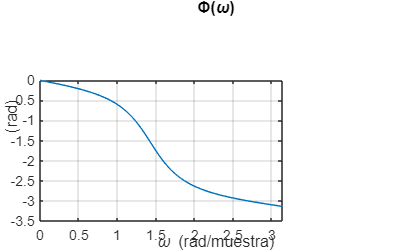

phase_iir = -cumtrapz(w, tau_iir);
plot_spec(w, phase_iir, "\Phi(\omega)", "\omega (rad/muestra)"); % 
ylabel("(rad)")

En principio podría parecer un contrasentido calcular la fase a partir de su derivada si no fuera porque existe una forma indirecta para calcular el retardo de grupo que evita las discontinuidades de la fase.

#### Tarea 3.2.5

Calcule el retardo de grupo del filtro FIR en $N=512$ frecuencias en el intervalo $[0,2\pi)$. Asigne el resultado a las variables `tau_fir` y `w`. Calcule también la fase continua integrando el retardo de grupo y asígnela a la variable `phase_fir`.

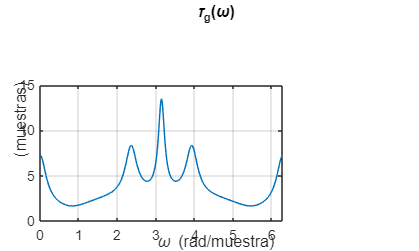

clear w tau_fir
% SU CÓDIGO AQUÍ
B_fir = [1, .89, -.93, -1.95, -.23, .75, -.48];
A_fir = 1;
[tau_fir, w] = grpdelay(B_fir, A_fir, 512, "whole");
phase_fir = -cumtrapz(w, tau_fir);
% --------------
plot_spec(w, tau_fir, "\tau_g(\omega)", "\omega (rad/muestra)"); 
ylabel("(muestras)"); 

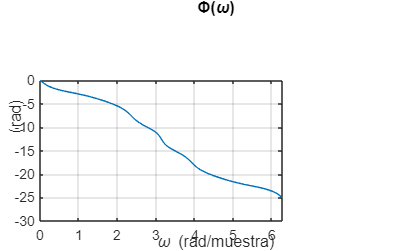

plot_spec(w, phase_fir, "\Phi(\omega)", "\omega (rad/muestra)"); 
ylabel("(rad)");

check_task(325, 'es');

>>>>> [3:2:5] Correcto.


### 2.3. Polos y ceros

Los filtros también se pueden representar y analizar mediante los polos y ceros de la función de transferencia. Los polos (ceros) son las raíces del polinomio denominador (numerador) que en MATLAB se especifican con el vector de coeficientes.

La función [`tf2zpk`](matlab: doc tf2zpk) calcula los ceros, polos y ganancia de un filtro a partir de los coeficientes $B$ y $A$

[z_iir, p_iir, k_iir] = tf2zpk(B_iir, A_iir)

z_iir =   -0.7500 + 0.6614i
  -0.7500 - 0.6614i


p_iir =    0.1000 + 0.7000i
   0.1000 - 0.7000i


k_iir = 0.5000

El diagrama de polos y ceros de un filtro puede representarse con la función [`zplane`](matlab: doc zplane). Los parámetros pueden ser los vectores (fila) de coeficientes o los vectores (columna) de polos y ceros:

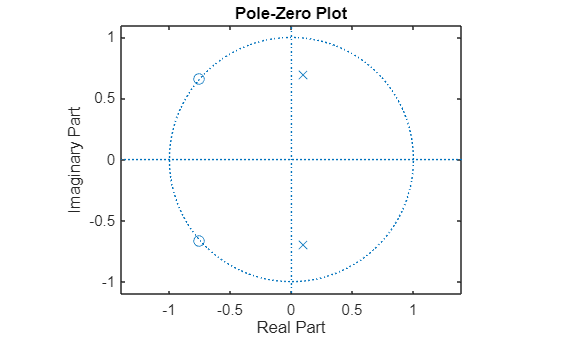

zplane(B_iir, A_iir)

zplane(z_iir, p_iir)

En ninguna de las alternativas se representa la región de convergencia. Recuérdese que los filtros son sistemas LTI causales por lo que la región de convergencia es la corona circular que se extiende desde el polo con mayor radio hasta el infinito. Con la descomposición anterior es fácil calcular el límite inferior de la corona $|z|>|r_{max}|$

r_max = max(abs(p_iir))

r_max = 0.7071

Para determinar si el filtro es estable puede comprobarse la condición $|r_{max}| < 1$

is_stable = r_max < 1

is_stable = logical
   1


o usar la función [`isstable`](matlab: doc isstable)

is_stable = isstable(B_iir, A_iir)

is_stable = logical
   1


#### Tarea 3.2.6

Calcule los polos, ceros y ganancia del filtro FIR. Asigne los resultados a las variables `z_fir`, `p_fir` y `k_fir`, respectivamente. Calcule también el límite inferior de su región de convergencia y asígnelo a la variable `r_max`.

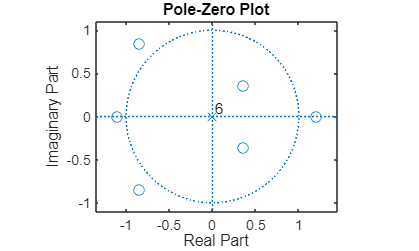

clear z_fir p_fir k_fir r_max
% SU CÓDIGO AQUÍ
[z_fir, p_fir, k_fir] = tf2zpk(B_fir, A_fir);
r_max = max(abs(p_fir));
% --------------
zplane(B_fir, A_fir)

check_task(326, 'es')

>>>>> [3:2:6] Correcto.


### 2.4. Retardo

El proceso de filtrado produce retardo debido al tiempo que necesita el sistema para reaccionar ante la entrada. Si el filtro es de FIR de fase lineal, el retardo puede calcularse y compensarse muy fácilmente a usando el retardo de grupo.

En el archivo `lab3.mat` hay un segmento de una señal electrocardiográfica con ruido y los coeficientes de varios filtros. El primero (coeficientes `B1`, `A1`) es un filtro FIR de fase lineal mientras que el segundo (coeficientes `B2`, `A2`) es un filtro IIR.

load("lab3.mat");

#### FIR de fase lineal

En la gráfica se muestra un segmento de la señal original y la filtrada con el filtro FIR

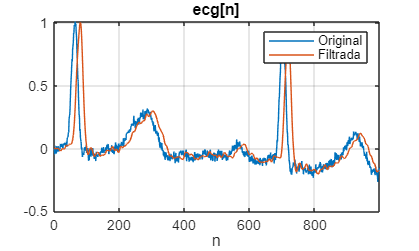

L = length(ecg);
N = (0:L-1)';
ecgf = filter(B1, A1, ecg);
plot_sig(N, [ecg, ecgf], "ecg[n]", "n");
legend("Original", "Filtrada"); 

El retardo que provoca el filtro FIR es constante en todas las frecuencias (por ser de fase lineal) como se puede ver en la gráfica del retardo de grupo:

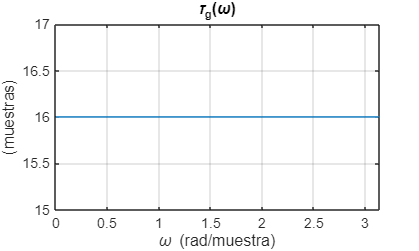

[tau1, w] = grpdelay(B1, A1);
plot_spec(w, tau1, "\tau_g(\omega)", "\omega (rad/muestra)"); 
ylabel("(muestras)"); 

Para compensar el retardo de valor `delay` se puede desplazar la señal filtrada eliminado sus primeras muestras y eliminar las últimas de la señal original.

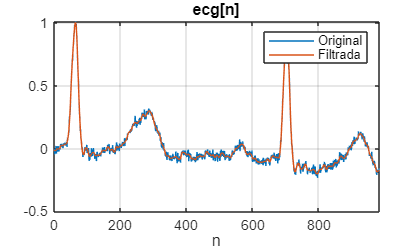

delay = tau1(1);
ecgfc = ecgf;
ecgfc(1:delay) = [];
ecgc = ecg(1:end-delay);
N = N(1:end-delay);
plot_sig(N, [ecgc, ecgfc], "ecg[n]", "n");
legend("Original", "Filtrada"); 

Ahora la entrada y la salida están perfectamente alineadas.

#### IIR

Los filtros IIR (y algunos FIR) no tienen fase lineal por lo que el retardo es una función de la frecuencia y no puede aplicarse el procedimiento anterior anterior.

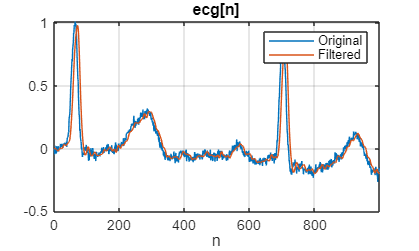

L = length(ecg);
N = (0:L-1)';
ecgf = filter(B2, A2, ecg);
plot_sig(N, [ecg, ecgf], "ecg[n]", "n");
legend("Original", "Filtrada"); 
legend("Original", "Filtered"); 

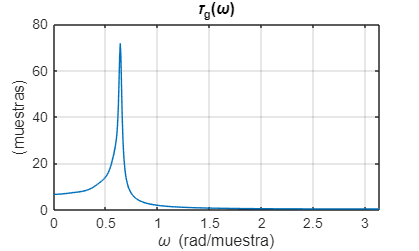

[tau2, w] = grpdelay(B2, A2);
plot_spec(w, tau2, "\tau_g(\omega)", "\omega (rad/muestra)"); 
ylabel("(muestras)"); 

En este caso se puede recurrir a la técnica de [filtrado anticausal de fase nula](https://www.mathworks.com/help/signal/ug/anti-causal-zero-phase-filter-implementation.html) implementada en MATLAB con la función [`filtfilt`](matlab: doc filtfilt) que filtra la señal dos veces: la primera con la señal original y la segunda con la señal reflejada. El proceso no es causal pero elimina completamente la distorsión de fase.

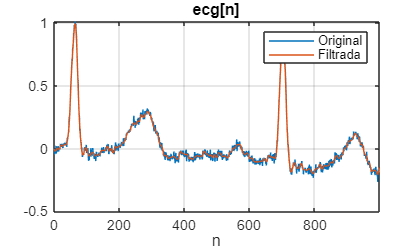

ecgfc = filtfilt(B2, A2, ecg);
plot_sig(N, [ecg, ecgfc], "ecg[n]", "n");
legend("Original", "Filtrada"); 

#### Tarea 3.2.7

En el archivo `lab3.mat` hay un tercer filtro FIR de fase lineal con coeficientes `B3` y `A3`. Use este filtro para filtrar la señal `ecg` y compense el retardo producido por el mismo. Asigne el retardo a la variable `delay`, la señal filtrada y recortada a la variable `ecgfc` y la señal original recortada a la variable `ecgc`.

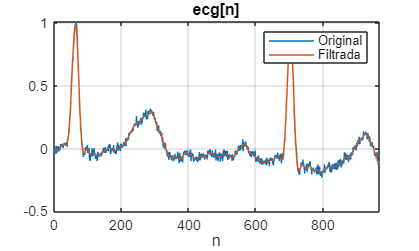

clear delay ecgc ecgfc
load("lab3.mat", "ecg", "B3", "A3");
% SU CÓDIGO AQUÍ
ecgf = filter(B3, A3, ecg);
[tau1, w] = grpdelay(B3, A3);
delay = tau1(1);
ecgfc = ecgf;
ecgfc(1:delay) = []; %desplaza
ecgc = ecg(1:end-delay);
% --------------
L = length(ecgc);
N = (0:L-1)';
plot_sig(N, [ecgc, ecgfc], "ecg[n]", "n");
legend("Original", "Filtrada"); 

check_task(327, 'es')

>>>>> [3:2:7] Correcto.


### 2.5. Transitorio

Cuando un filtro parte de reposo inicial necesita un cierto tiempo para alcanzar el régimen permanente. Este intervalo de tiempo se conoce como transitorio y depende de la respuesta al impulso ya que el régimen permanente se alcanza cuando ésta se anula (caso FIR) o se hace muy pequeña (caso IIR).

En el caso FIR, el transitorio es igual al orden del filtro que, a su vez, es una unidad menor que la longitud del vector de coeficientes `B`.

En la siguiente gráfica se muestra una sinusoide filtrada con el primer filtro FIR del archivo `lab3.mat`, en la que se muestra una línea vertical que marca el final del régimen transitorio y el comienzo del régimen permanente.

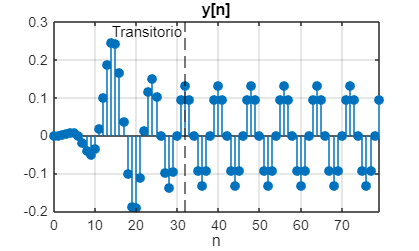

T1 = length(B1)-1;
L = 80;
N = (0:L-1)';
x = cos(pi*N/4);
y = filter(B1, A1, x);
plot_sig(N, y, "y[n]", "n")
xline(T1, "k--", "Transitorio", LabelOrientation="horizontal", LabelHorizontalAlignment="left")

Para el caso IIR puede usarse la función [`impzlength`](matlab: doc impzlength) para estimar la longitud de la respuesta al impulso antes de hacerse suficientemente pequeña, en este caso menor que $10^{-2}$.

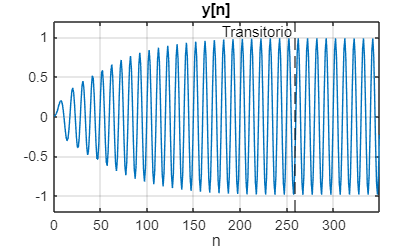

T2 = impzlength(B2, A2, .01);
L = 350;
N = (0:L-1)';
x = cos(pi*N/5);
y = filter(B2, A2, x);
plot_sig(N, y, "y[n]", "n")
ylim([-1.2, 1.2])
xline(T2, "k--", "Transitorio", LabelOrientation="horizontal", LabelHorizontalAlignment="left")

#### Tarea 3.2.8

Asigne a la variable `T3` la longitud del transitorio del filtro FIR con coeficientes `B3` y `A3` contenido en el archivo `lab3.mat`.

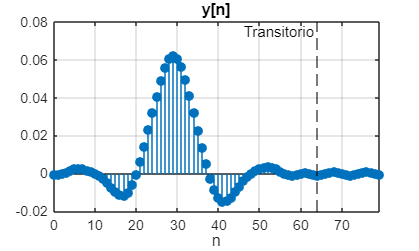

clear T3
load("lab3.mat", "B3", "A3");
% SU CÓDIGO AQUÍ
T3 = length(B3)-1;
L = 80;
N = (0:L-1)';
x = cos(pi*N/4);
y = filter(B3, A3, x);
plot_sig(N, y, "y[n]", "n")
xline(T3, "k--", "Transitorio", LabelOrientation="horizontal", LabelHorizontalAlignment="left")

% --------------
check_task(328, 'es')

>>>>> [3:2:8] Correcto.


## 3. Diseño

Se abordan ahora algunas cuestiones relativas al diseño de filtros. En particular se examinan los métodos de diseño de filtros IIR invariancia al impulso y transformación bilineal. Después se revisa el método de la vantana para el diseño de filtros FIR. En todos los casos el análisis se hace desde la perspectiva de MATLAB.

### 3.1.- Invariancia al impulso

El método de diseño de invariancia al impulso consiste en muestrear la respuesta al impulso de un filtro continuo $h_c(t)$ para obtener el equivalente discreto $h[n]=Th_c(nT)$, con $T$ el periodo de muestreo. El principal inconveniente es que el filtro continuo se representa con su función de transferencia $H_c(s)$, que es una transformada de Laplace. Un algoritmo alternativo consiste en manipular la función de transferencia continua cambiando los polos del filtro continuo por los correspondientes discretos para obtener directamente los coeficentes del filtro discreto. Ese es el método que usa la función [`impinvar`](matlab: doc impinvar).

En el siguiente código se transforma el filtro continuo con función de transferencia


$$H(s)=\frac{3500}{s^2+60s+3700}$$


al equivalente discreto usando el método de la invariancia al impulso. Para comprobar el resultado se pintan en la misma gráfica un segmento de $0.1\,\rm{s}$ de las respuestas al impulso continua (escalada) y discreta.

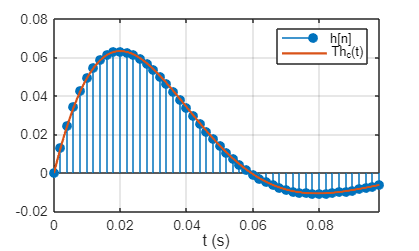

Fs = 500;
Bs = [0, 0, 3500];
As = [1, 60, 3700];
[r, p] = residue(Bs, As);
t = linspace(0, .1, 1000);
hs = r.'*exp(p.*t)/Fs;
[Bz, Az] = impinvar(Bs, As, Fs);
[hz, N] = impz(Bz, Az, 50);
plot_sig(N/Fs, hz, "", "t (s)")
hold on, plot(t, hs, LineWidth=1.5), hold off
legend("h[n]", "Th_c(t)")

Note que los vectores de coeficientes del filtro continuo se construyen en potencias decrecientes de la variable $s$. Los dos primeros ceros de `Bs` son los coeficientes del numerador en $s^2$ y $s$, respectivamente.

#### Tarea 3.3.1

Aplique el método de invariancia al impulso para convertir el filtro continuo con función de transferencia


$$H(s)=\frac{0.89s^2+0.25s+10}{s^2+250s+56000}$$


en su equivalente discreto usando la frecuencia de muestreo $F_s=1\,\rm{kHz}$.

Después, calcule $N=40$ muestras de la respuesta al impulso del filtro discreto y asígnelas al vector `h`.

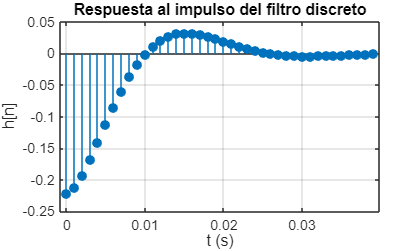

clear h
% SU CÓDIGO AQUÍ
% Parámetros del filtro continuo y frecuencia de muestreo
Bs = [0.89, 0.25, 10];    % Coeficientes del numerador (potencias de s)
As = [1, 250, 56000];     % Coeficientes del denominador (potencias de s)
Fs = 1e3;                 % Frecuencia de muestreo en Hz
N = 40;                   % Número de muestras de la respuesta al impulso

[r, p] = residue(Bs, As);
t = linspace(0, .1, 1000);
h = r.'*exp(p.*t)/Fs;

% Convertir el filtro continuo a su equivalente discreto usando invariancia al impulso
[Bz, Az] = impinvar(Bs, As, Fs);

% Calcular las primeras N muestras de la respuesta al impulso del filtro discreto
[h, n] = impz(Bz, Az, N);

% Graficar la respuesta al impulso discreta
stem(n / Fs, h, 'filled');
xlabel('t (s)');
ylabel('h[n]');
title('Respuesta al impulso del filtro discreto');
grid on;

% --------------
check_task(331, 'es')

>>>>> [3:3:1] Correcto.


### 3.3.- Transformación bilineal

El método más habitual de diseño de filtros IIR se basa en la aplicación de la transformación bilineal a un filtro prototipo analógico. Los tipos de filtro prototípicos clásicos son Butterworth, Chebysev I, Chebysev II y Elíptico. El procedimiento de diseño está tan estandarizado que las funciones de diseño permiten trabajar en el dominio discreto ocultando todos los detalles algorítmicos.

El primer paso del diseño es determinar el tipo y el orden del filtro necesario. El tipo es una decisión del usuario mientras que el orden $N$ depende de los parámetros de diseño siguientes: $\omega_p$ (frecuencia de paso normalizada), $\omega_s$ (frecuencia de rechazo normalizada), $R_p$ (rizado en la banda de paso) y $R_s$ (mínima atenuación en la banda rechazada).

MATLAB dispone de las funciones [`buttord`](matlab: doc buttord), [`cheb1ord`](matlab: doc cheb1ord), [`cheb2ord`](matlab: doc cheb2ord) y [`ellipord`](matlab: doc ellipord) para calcular el orden mínimo que garantiza que se cumplen las especificaciones de diseño expresadas con los parámetros anteriores.

Por ejemplo, el cálculo del orden mínimo necesario para un filtro discreto de tipo Chebyshev I equivalente a un filtro continuo con las siguientes especificaciones: frecuencia de muestreo $F_s=40\,\rm{kHz}$, frecuencia de paso $f_p=4\,\rm{kHz}$, frecuencia de rechazo $f_s=8\,\rm{kHz}$, rizado en la banda de paso de $R_p=0.5\,\rm{dB}$ y atenuación mínima en la banda atenuada de $R_s=40\,\rm{dB}$, se hace con

Fs = 40e3; %  frecuencia de muestreo
fp = 4e3; %  frecuencia de paso
fs = 8e3; %  frecuencia de rechazo
Rp = 0.5; %  rizado en la banda de paso
Rs = 40; %  atenuación mínima en la banda atenuada
Wp = fp/(Fs/2); %  frecuencia de paso normalizada
Ws = fs/(Fs/2); %  frecuencia de rechazo normalizada
N = cheb1ord(Wp, Ws, Rp, Rs)

N = 5

MATLAB usa la normalización de frecuencias en todas las funciones de diseño. Consiste en transformar las frecuencias discretas de modo que el intervalo $[0,\pi)$ se convierta en $[0,1)$, por lo que el valor $\pi$ (o la correspondiente frecuencia continua $F_s/2$) se asigna al valor $1$.

Nótese que la variable con la frecuencia de muestreo es `Fs` para diferenciarla de la variable con la frecuencia de rechazo `fs`.

#### Tarea 3.3.2

Determine los órdenes mínimos de dos filtros IIR de tipo Butterworth y Elíptico equivalentes a un filtro continuo con las siguientes especificaciones: frecuencia de muestreo $F_s=7\,\rm{kHz}$, frecuencia de paso $f_p=1.4\,\rm{kHz}$, frecuencia de rechazo $f_s=2.1\,\rm{kHz}$, rizado en la banda de paso de $R_p=0.4\,\rm{dB}$ y atenuación mínima en la banda atenuada de $R_s=50\,\rm{dB}$.

Asigne los resultados a las variables `N_butt` y `N_ellip`, respectivamente.

clear N_butt N_ellip
% SU CÓDIGO AQUÍ
Fs = 7e3; %  frecuencia de muestreo
fp = 1.4e3; %  frecuencia de paso
fs = 2.1e3; %  frecuencia de rechazo
Rp = 0.4; %  rizado en la banda de paso
Rs = 50; %  atenuación mínima en la banda atenuada
Wp = fp/(Fs/2); %  frecuencia de paso normalizada
Ws = fs/(Fs/2); %  frecuencia de rechazo normalizada
N_butt = buttord(Wp, Ws, Rp, Rs)

N_butt = 11

N_ellip = ellipord(Wp, Ws, Rp, Rs)

N_ellip = 5

% --------------
check_task(332, 'es')

>>>>> [3:3:2] Correcto.


Una vez concocido el orden del filtro se usan las funciones [`butter`](matlab: doc butter), [`cheby1`](matlab: doc cheby1), [`cheby2`](matlab: doc cheby2) o [`ellip`](matlab: doc ellip) para calcular sus coeficientes segun el tipo deseado. Los parámetros que usan no son siempre los mismos por los detalles algorítmicos de cada uno de los tipos. Por ejemplo, el diseño de un filtro de Butterworth requiere el orden y la frecuencia de paso, mientras que el diseño de un filtro elíptico requiere además el rizado en la banda de paso y la atenuación en la banda rechazada. Además se puede indicar el tipo de filtro con los parámetros `'low'` (por defecto), `'high'`, `'bandpass'` y `'stop'`, para diseñar filtros paso bajo, paso alto, paso banda y banda rechazada, respectivamente. En los dos últimos casos, las frecuencias deben indicarse con un vector que incluya la frecuencia de cada borde.

Por ejemplo, para diseñar un filtro elíptico paso banda de orden $N=8$ con frecuencias de paso normalizadas $W_{pL}=0.3$, $W_{pH}=0.5$, rizado en la banda de paso $R_p = 0.4\,\mathrm{dB}$ y atenuación en la banda rechazada de $R_s = 50\,\rm{dB}$ se usa

N = 8;
Wp = [.3, .5];
Rp = 0.4;
Rs = 50;
[B, A] = ellip(N, Rp, Rs, Wp, 'bandpass');

El módulo de la respuesta en frecuencia (en decibelios) es

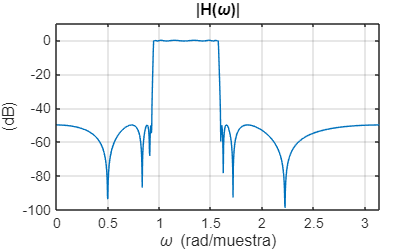

[H, w] = freqz(B, A, 1024);
plot_spec(w, mag2db(abs(H)), "|H(\omega)|", "\omega (rad/muestra)") 
ylim([-100, 10]), ylabel("(dB)")

#### Tarea 3.3.3

Diseñe un filtro Chebyshev tipo II paso alto, de orden $N=12$, con frecuencia de paso normalizada $W_{p}=0.4$ y atenuación en la banda rechazada de $R_s = 60\,\rm{dB}$. Asigne los vectores de coeficientes a las variables `B` y `A`.

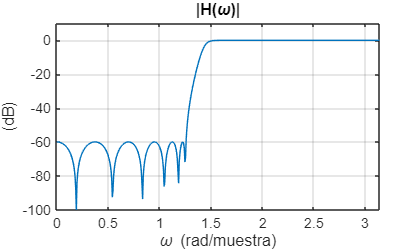

clear B A
% SU CÓDIGO AQUÍ
N = 12;
Wp = .4;
Rs = 60;
[B, A] = cheby2(N, Rs, Wp,"high");
% --------------
[H, w] = freqz(B, A);
plot_spec(w, mag2db(abs(H)), "|H(\omega)|", "\omega (rad/muestra)") 
ylim([-100, 10]), ylabel("(dB)")

check_task(333, 'es')

>>>>> [3:3:3] Correcto.


### 3.2.- Filtros FIR

Los filtros FIR son exclusivamente discretos. Hay múltiples algoritmos para calcular los coeficientes (enventanado, muestreo en frecuencia, optimización Parks-MacLellan, mínimos cuadrados...). En MATLAB muchos de ellos están codificados como funciones. El método del enventanado, consistente en truncar la respuesta al impulso ideal y aplicar una ventana a los coeficientes para minimizar el fenómeno de Gibbs, está implementado por la función [`fir1`](matlab: doc fir1). Los parámetros requeridos son el orden $N$ y la frecuencia de corte normalizada $W_c$. Además, se puede indicar la ventana (Hamming, por defecto) y el tipo de filtro (paso bajo, paso alto...).

Por ejemplo, un filtro FIR paso bajo de orden $N=32$ con frecuencia de corte normalizada $W_c=.25$ y ventana de Hamming se calcula con

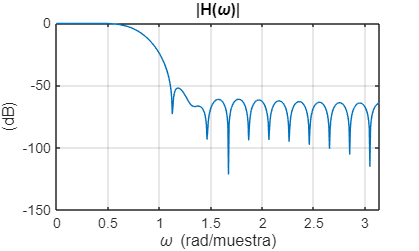

N = 32;
Wp = .25;
B = fir1(N, Wp, hamming(N+1)); %  o fir1(N, Wp) porque Hamming es la ventana por defecto 
[H, w] = freqz(B, 1);
plot_spec(w, mag2db(abs(H)), "|H(\omega)|", "\omega (rad/muestra)") 
ylabel("(dB)")

#### Tarea 3.3.4

Use la función [`fir1`](matlab: doc fir1) para diseñar un filtro FIR paso alto, de orden $N=64$, con frecuencia de corte $\omega_c=3\pi/4$ y ventana de Blackman (función [`blackman`](matlab: doc blackman)). Asigne el vector de coeficientes a la variables `B`. No olvide normalizar la frecuencia de paso.

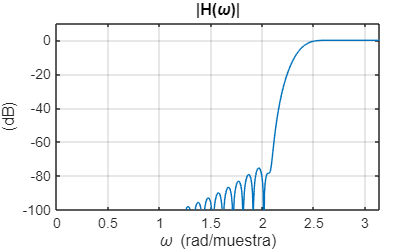

clear B
% SU CÓDIGO AQUÍ
N = 64;
Wp = 3/4;
B = fir1(N, Wp,'high', blackman(N+1));
% --------------
A = 1;
[H, w] = freqz(B, A);
plot_spec(w, mag2db(abs(H)), "|H(\omega)|", "\omega (rad/muestra)") 
ylim([-100, 10]), ylabel("(dB)")

check_task(334, 'es')

>>>>> [3:3:4] Correcto.


Con la ventana de Kaiser existe un procedimiento para calcular el orden del filtro que está implementado en la función [`kaiserord`](matlab: doc kaiserord). La función necesita un vector con la definición de la banda de frecuencias normalizadas, un vector de magnitudes correspondientes con cada una de las frecuencias y un vector con las desviaciones máximas (en unidades lineales) en la banda de paso $\delta_p$ y atenuada $\delta_s$. La función devuelve el orden $N$, la frecuencia de corte normalizada $W_c$ y el parámetro $\beta$ de la ventana de Kaiser, que son los parámetros necesarios para llamar a la función [`fir1`](matlab: doc fir1).

Por ejemplo, para diseñar un filtro FIR paso bajo con frecuencia de rechazo $\omega_s = \pi/3$, rizado en la banda de paso $R_p=1\,\rm{dB}$, atenuación en la banda rechazada de $R_s=60\,\rm{dB}$ y ventana de Kaiser

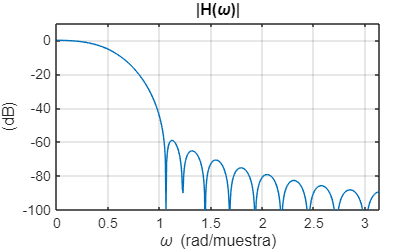

Rp = 1;
delta_p = 1 - 10^(-Rp/20);
Rs = 60;
delta_s = 10^(-Rs/20);
Ws = [0, 1/3];
Mgs = [1, 0];
devs = [delta_p, delta_s];
[N, Wn, beta] = kaiserord(Ws, Mgs, devs);
B = fir1(N, Wn, kaiser(N+1, beta));
A = 1;
[H, w] = freqz(B, A);
plot_spec(w, mag2db(abs(H)), "|H(\omega)|", "\omega (rad/muestra)") 
ylim([-100, 10]), ylabel("(dB)")

Recuerde las expresiones $R_p=-20\log_{10}(1-\delta_p)$ y $R_s=-20\log_{10}(\delta_s)$ necesarias para convertir los datos de unidades lineales a decibelios.

#### Tarea 3.3.5

Use el método de la ventana de Kaiser para diseñar un filtro FIR paso alto con frecuencia de rechazo $\omega_s=3\pi/4$, rizado en la banda de paso $R_p=0.5\,\rm{dB}$, atenuación en la banda rechazada de $R_s=50\,\rm{dB}$. Asigne el vector de coeficientes a la variables `B`. Indique la frecuencia máxima de la banda como `1-eps`.

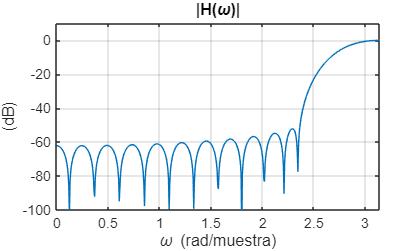

clear B
% SU CÓDIGO AQUÍ
Rp = 0.5;
delta_p = 1 - 10^(-Rp/20);
Rs = 50;
delta_s = 10^(-Rs/20);
Ws = [ 3/4 , 1-eps];
Mgs = [0, 1];
devs = [delta_p, delta_s];

[N, Wn, beta] = kaiserord(Ws, Mgs, devs);
B = fir1(N, Wn, kaiser(N+1, beta), 'high');
% --------------
A = 1;
[H, w] = freqz(B, A);
plot_spec(w, mag2db(abs(H)), "|H(\omega)|", "\omega (rad/muestra)") 
ylim([-100, 10]), ylabel("(dB)")

check_task(335, 'es')

>>>>> [3:3:5] Correcto.


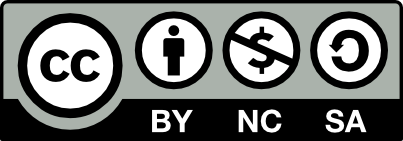 Práctica 3 © 2024 por José Parera licenciada bajo [CC BY-NC-SA 4.0](https://creativecommons.org/licenses/by-nc-sa/4.0/?ref=chooser-v1)